# **NGPCA: Clustering high-dimensional and non-stationary data streams Please cite this code using the following DOI: **[**https://doi.org/10.1016/j.patcog.2023.110030**](https://doi.org/10.1016/j.patcog.2023.110030)

clear variables
close all
addpath('ngpca', 'data');
% Reproducability
rng(0)

Load the ring-line-square and vortex data sets

load rls.mat -ASCII;
vortex = vortex(6*pi, 120, 20, 4000);

Create an NGPCA object with hard-clustering. Set the data vector to the rls data initialize the units. Start the training processes and swap the distribution towards the vortex mid training

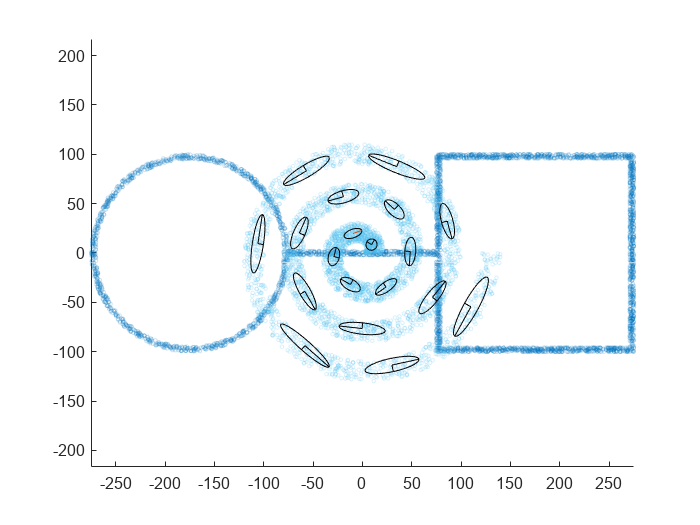

ngpca = NGPCA('softhard', 1);
figure;
data = rls;
scatter(data(:,1), data(:,2),5,'o','MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
hold on;
axis equal;
axis manual;
ngpca = init_units(ngpca, data, 19, 'iterations', 40000, 'PCADimensionality', 2);
for i = 1:ngpca.iterations
    % Sample a random data point in each iteration
    ngpca = fit_single(ngpca, data(ceil(size(data,1) .* rand), :));
    % Needed to overwrite the ngpca object if plotted in a loop to delete
    % units from previous plot
    if mod(i,100) == 0
        ngpca = ngpca.draw();
    end
    if i == 20000
        data = vortex;
        scatter(data(:,1), data(:,2),5,'o','MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
    end
end